# Physics-Informed Neural Networks (PINNs) for Option Pricing

The Black-Scholes equation is a widely used mathematical model for pricing options and other financial derivatives. It describes the price evolution of an option over time, taking into account factors such as the underlying asset price, volatility, risk-free interest rate, and the option's strike price and maturity. 

The Black-Scholes equation is a partial differential equation (PDE) of the form:


$$%\begin{equation*}
\frac{\partial V}{\partial t} + \frac{1}{2}\sigma^2 S^2 \frac{\partial^2 V}{\partial S^2} + rS\frac{\partial V}{\partial S} - rV = 0
\end{equation*}$$



$$V(T,S)=K(S)$$


where $V(t,S)$ is the price of the option as a function of stock price $S$ and time $t$, $r$ is the risk-free interest rate, and $\sigma$ is the volatility of the stock returns.

The Black-Scholes equation has an analytical solution, known as the Black-Scholes formula, which gives the exact option price under certain assumptions. However, in more complex scenarios or when the assumptions are violated, numerical methods are often employed to solve the equation. 

**Physics-Informed Neural Networks (PINNs)** are a class of deep learning models that incorporate physical laws and domain knowledge into the neural network training process. PINNs are particularly useful for solving PDEs and other physical systems, as they can learn the solution while respecting the underlying governing equations. 

The key idea behind PINNs is to use the neural network to represent the solution to the PDE and then define a loss function that consists of two parts: 

- The mismatch between the neural network predictions and the initial and boundary conditions. 

- The residual of the PDE, which measures how well the neural network satisfies the governing equation.

By minimizing this composite loss function, the neural network learns to approximate the solution to the PDE while adhering to the physical constraints. 

## Solving the Black-Scholes Equation with PINNs 

In this example, we demonstrate how to solve the Black-Scholes equation using PINNs in MATLAB. The main steps involved are: 

- Generate training data: We create a set of input points (stock prices and times) and corresponding initial and boundary conditions based on the Black-Scholes formula.

- Define the neural network architecture: We construct a fully connected neural network with a suitable number of layers and neurons to represent the option price function.

- Customize the loss function: We implement a customized loss function that includes the mismatch between the neural network predictions and the initial and boundary conditions, as well as the residual of the Black-Scholes equation. 

- Train the neural network: We use the Adam optimizer algorithm to minimize the loss function and learn the optimal network parameters.

- Evaluate the trained model: We compare the neural network predictions with the analytical solutions.

clear;
clc; close;
rng(100,'twister') % Set up the random seed

## Option Settings

K = 40;         % Strike Price
r = 0.05;       % Interest Rate
sigma = 0.25;   % Annualized volatility of asset
T = 1;          % Time to maturity
S_max = 500;
S_range = [0, S_max];  % Input ranges for asset price
t_range = [0, T];    % Input ranges for time

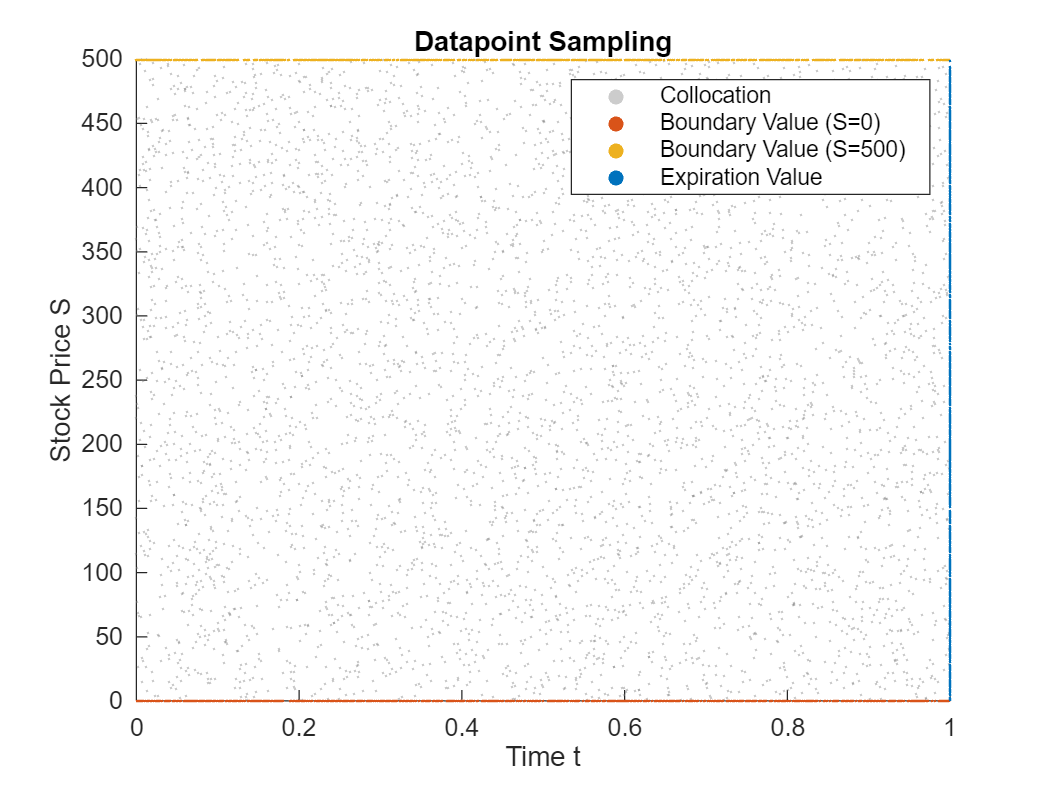

gs = @(x) max(x - K, 0);  % Intrinsic value

get_diff_data = @(n) [rand(n, 1)*(t_range(2)-t_range(1))+t_range(1), ...
    rand(n, 1)*(S_range(2)-S_range(1))+S_range(1), ...
    zeros(n, 1)];

get_bvp_data = @(n) get_bvp_data_fcn(n,S_range,sigma,K,r,t_range);

get_evp_data = @(n) get_evp_data_fcn(n,S_range,gs);

plot_n_pde = 5000;
plot_n_bvp = 1000;
plot_n_evp = 1000;
plot_diff = get_diff_data(plot_n_pde);
plot_X1 = plot_diff(:, 1:2);
plot_bvp = get_bvp_data(plot_n_bvp);
plot_X21 = plot_bvp(1:plot_n_bvp, 1:2);  % S=0
plot_X22 = plot_bvp(plot_n_bvp+1:end, 1:2);   % S=500
plot_evp = get_evp_data(plot_n_evp);
plot_X3 = plot_evp(:, 1:2);

figure;
scatter(plot_X1(:,1), plot_X1(:,2), 1, 'filled', 'MarkerFaceAlpha', 0.4, 'MarkerEdgeColor', 'none', 'MarkerFaceColor', [0.5, 0.5, 0.5]);
hold on;
scatter(plot_X21(:,1), plot_X21(:,2), 1, 'filled', 'MarkerFaceColor', '#D95319');
scatter(plot_X22(:,1), plot_X22(:,2), 1, 'filled', 'MarkerFaceColor', '#EDB120');
scatter(plot_X3(:,1), plot_X3(:,2), 1, 'filled', 'MarkerFaceColor', '#0072BD');
xlabel('Time t');
ylabel('Stock Price S');
title('Datapoint Sampling');
legend('Collocation', 'Boundary Value (S=0)', 'Boundary Value (S=500)', 'Expiration Value');
ylim([0, S_max]);
xlim([0, 1]);
hold off;

## Set up the Neural Networks

We can visualize and change the settings from [Deep Network Designer](https://www.mathworks.com/help/deeplearning/gs/get-started-with-deep-network-designer.html). In this app, you easily build deep learning networks interactively. Analyze the neural networks to check if the defined architecture is correct and detect problems before training.

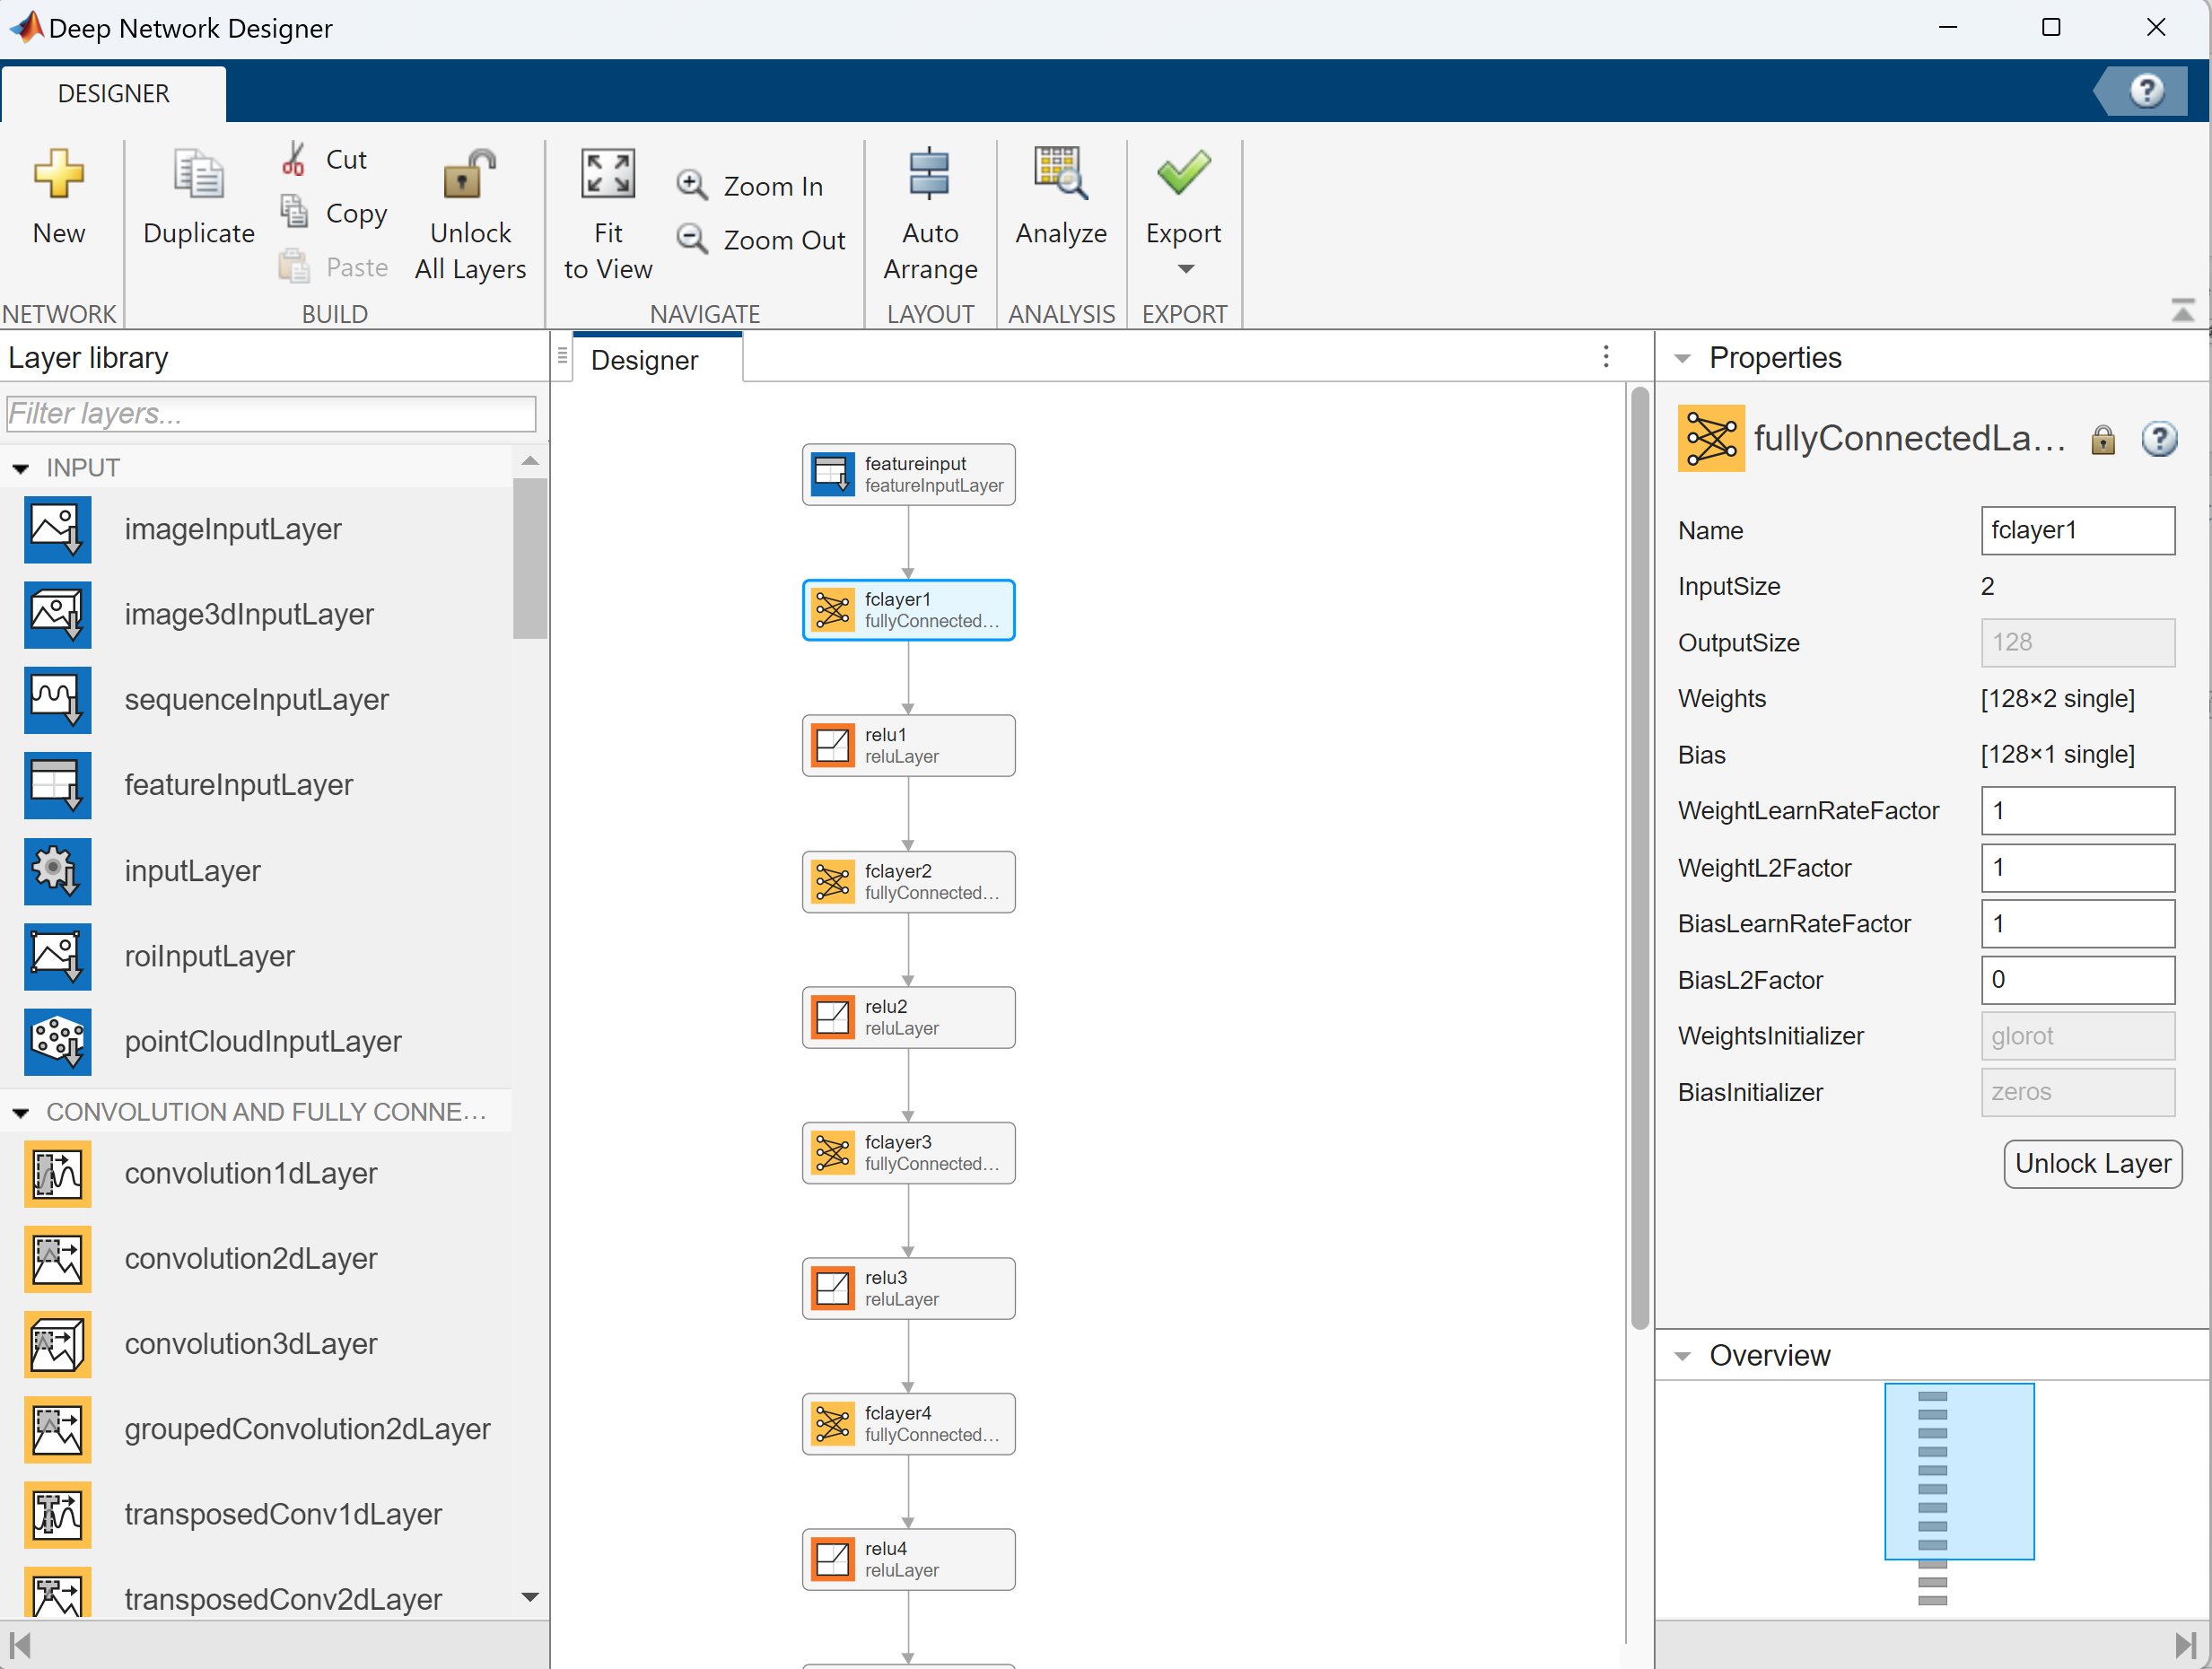

input_dim = 2;
hidden_dim = 128;
output_dim = 1;

layers = [
    featureInputLayer(input_dim, 'Name', 'featureinput')
    fullyConnectedLayer(hidden_dim, 'Name', 'fclayer1', 'WeightsInitializer', 'glorot', 'BiasInitializer', 'zeros')
    reluLayer('Name', 'relu1')
    fullyConnectedLayer(hidden_dim, 'Name', 'fclayer2', 'WeightsInitializer', 'glorot', 'BiasInitializer', 'zeros')
    reluLayer('Name', 'relu2')
    fullyConnectedLayer(hidden_dim, 'Name', 'fclayer3', 'WeightsInitializer', 'glorot', 'BiasInitializer', 'zeros')
    reluLayer('Name', 'relu3')
    fullyConnectedLayer(hidden_dim, 'Name', 'fclayer4', 'WeightsInitializer', 'glorot', 'BiasInitializer', 'zeros')
    reluLayer('Name', 'relu4')
    fullyConnectedLayer(hidden_dim, 'Name', 'fclayer5', 'WeightsInitializer', 'glorot', 'BiasInitializer', 'zeros')
    reluLayer('Name', 'relu5')
    fullyConnectedLayer(output_dim, 'Name', 'output', 'WeightsInitializer', 'glorot', 'BiasInitializer', 'zeros')];


pinns = dlnetwork(layers);
disp(['Check if pinn is a dlnetwork: ', num2str(isa(pinns, 'dlnetwork'))])

Check if pinn is a dlnetwork: 1


% deepNetworkDesigner(pinns);

## Train the neural networks

We set the number epoch is $5000$, and initial learning rate is $5\times 10^{-5}$. You can also use the Experiment Manager for the hyperparameter tuning.

numEpochs = 5000;
initialLearnRate = 5e-5;
iteration = 0;
printInterval = 50;
averageGrad = [];
averageSqGrad = [];
accLossFcn = dlaccelerate(@customLossFcn);
clearCache(accLossFcn);

for epoch = 1:numEpochs
    n_pde = 5000;
    n_bvp = 5000;
    n_evp = 5000;
    diff_data = get_diff_data(n_pde);
    X1 = diff_data(:, 1:2);
    y1 = diff_data(:, 3);
    bvp_data = get_bvp_data(n_bvp);
    X21 = bvp_data(1:n_bvp, 1:2);
    y21 = bvp_data(1:n_bvp, 3);
    X22 = bvp_data((n_bvp+1):end, 1:2);
    y22 = bvp_data((n_bvp+1):end, 3);
    evp_data = get_evp_data(n_evp);
    X3 = evp_data(:, 1:2);
    y3 = evp_data(:, 3);
    dlX1 = dlarray(X1.', 'CB');
    dlX21 = dlarray(X21.', 'CB');
    dlX22 = dlarray(X22.', 'CB');
    dlX3 = dlarray(X3.', 'CB');
    dly1 = dlarray(y1.', 'CB');
    dly21 = dlarray(y21.', 'CB');
    dly22 = dlarray(y22.', 'CB');
    dly3 = dlarray(y3.', 'CB');

    [totalLoss, pdeLoss, bvp1Loss, bvp2Loss, evpLoss, gradients] = dlfeval(accLossFcn, pinns, dlX1, dlX21, dlX22, dlX3, dly1, dly21, dly22, dly3, sigma, r);
    iteration = iteration + 1;
    [pinns, averageGrad, averageSqGrad] = adamupdate(pinns, gradients, averageGrad, averageSqGrad, iteration, initialLearnRate);

    if mod(epoch, printInterval) == 1
        if mod(epoch, printInterval) == 1
            fprintf('Epoch %d, Total Loss: %.2f, PDE Loss: %.2f, BVP1 Loss: %.2f, BVP2 Loss: %.2f, EVP Loss: %.2f\n', epoch, extractdata(totalLoss), extractdata(pdeLoss), extractdata(bvp1Loss), extractdata(bvp2Loss), extractdata(evpLoss));
        end
    end
end

Epoch 1, Total Loss: 145358.55, PDE Loss: 0.00, BVP1 Loss: 0.00, BVP2 Loss: 110811.63, EVP Loss: 34546.91
Epoch 51, Total Loss: 109048.64, PDE Loss: 0.00, BVP1 Loss: 0.00, BVP2 Loss: 84088.58, EVP Loss: 24960.06
Epoch 101, Total Loss: 64980.08, PDE Loss: 0.00, BVP1 Loss: 0.00, BVP2 Loss: 50080.71, EVP Loss: 14899.37
Epoch 151, Total Loss: 14783.65, PDE Loss: 0.00, BVP1 Loss: 0.00, BVP2 Loss: 11699.74, EVP Loss: 3083.91
Epoch 201, Total Loss: 286.86, PDE Loss: 0.01, BVP1 Loss: 0.00, BVP2 Loss: 113.57, EVP Loss: 173.28
Epoch 251, Total Loss: 207.56, PDE Loss: 0.16, BVP1 Loss: 0.00, BVP2 Loss: 12.66, EVP Loss: 194.75
Epoch 301, Total Loss: 201.92, PDE Loss: 0.51, BVP1 Loss: 0.00, BVP2 Loss: 13.37, EVP Loss: 188.05
Epoch 351, Total Loss: 192.63, PDE Loss: 1.26, BVP1 Loss: 0.00, BVP2 Loss: 12.03, EVP Loss: 179.34
Epoch 401, Total Loss: 178.91, PDE Loss: 3.00, BVP1 Loss: 0.00, BVP2 Loss: 11.29, EVP Loss: 164.62
Epoch 451, Total Loss: 166.59, PDE Loss: 5.82, BVP1 Loss: 0.00, BVP2 Loss: 11.26,

## Model Evaluation

In this section, we compare the numerical solutions with the analytic solutions to Black Scholes PDE at different maturity time $T=0.25, 0.5, 0.75, 1$. 

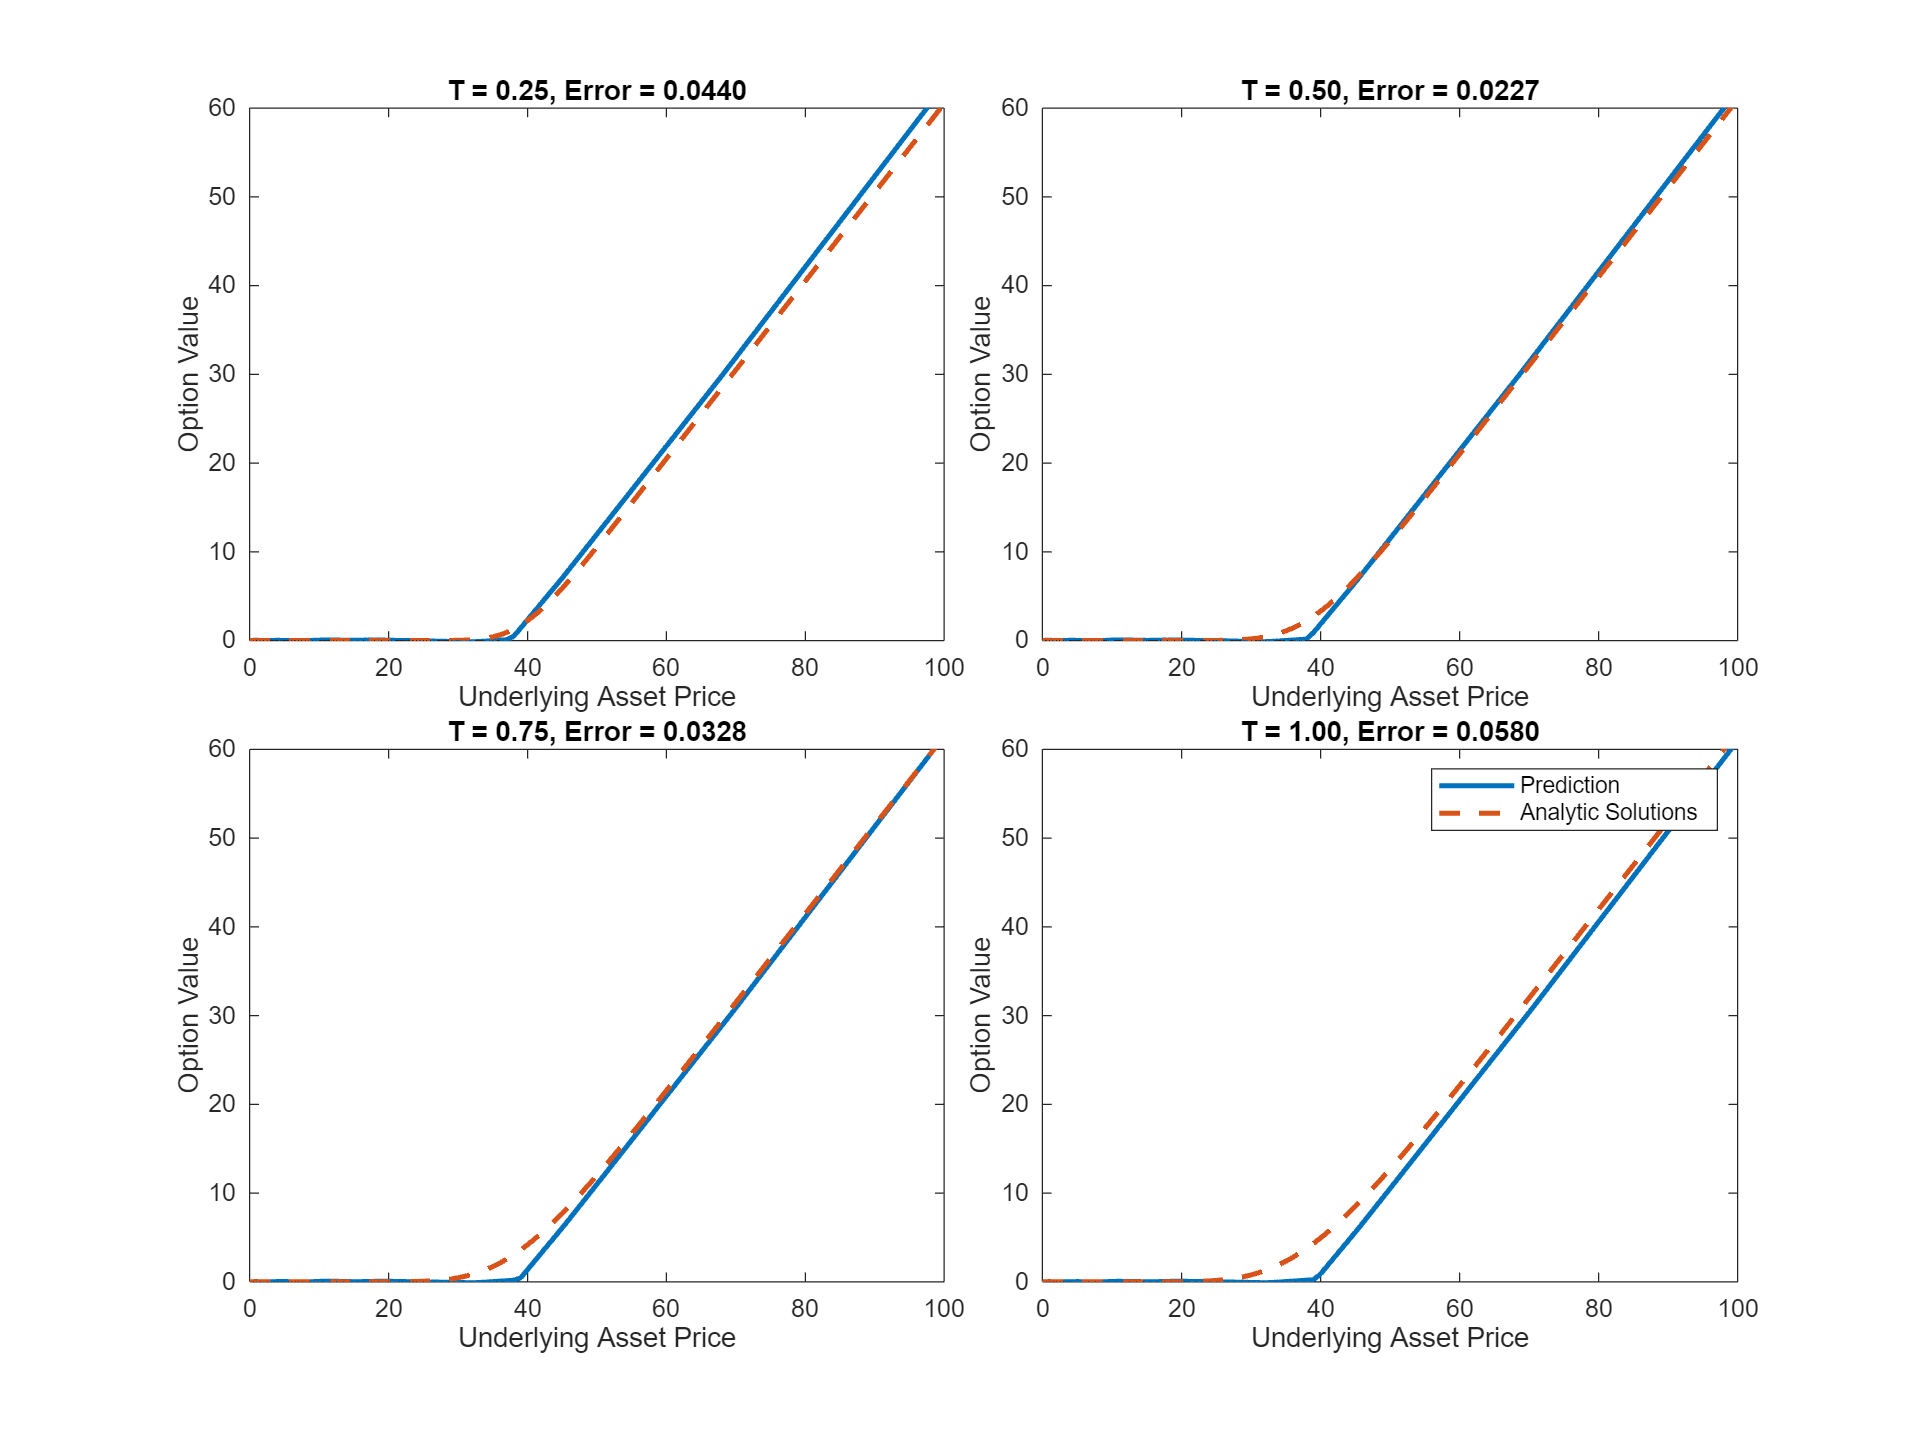

TTest = [0.25, 0.5, 0.75, 1.0];
numPredictions = 101;
STest = linspace(0.01, 100, numPredictions);
STest = dlarray(STest, "CB");

figure('Position', [100, 100, 1024, 768]);
tiledlayout(2, 2, "TileSpacing", "tight");

for i = 1:numel(TTest)
    T = TTest(i);
    TTestI = T * ones(1, numPredictions);
    TTestI = dlarray(TTestI, "CB");

    % Make predictions
    STTest = cat(1, TTestI, STest);
    VPred = forward(pinns, STTest);
    VPred = extractdata(VPred);

    % Calculate target using Black-Scholes analytic solution
    VTest = blsprice(extractdata(STest), K, r, T, sigma);

    % Calculate error
    err = norm(VPred - VTest) / norm(VTest);

    % Plot prediction
    nexttile;
    plot(STest, VPred, "-", 'LineWidth', 2);
    ylim([0, 60]);

    % Plot target
    hold on;
    plot(STest, VTest, "--", 'LineWidth', 2);
    hold off;

    xlabel("Underlying Asset Price");
    ylabel("Option Value");
    title(sprintf("T = %.2f, Error = %.4f", T, err));
end

legend("Prediction", "Analytic Solutions");

Comparing the prediction and analytical solutions, the PINNs approximation has the accuracy in the shape of the true solutions. However, the PINNs perform underestimates from the analytic solutions as the maturity time $T$ increases. The accuracy could be improved by considering different types of loss functions. In the current settings, the total loss function is consisted by three components: PDE loss, initial value loss, and boundary value loss. The results may be improved by trying smooth $L1$ loss. Another way is to try different neural networks. The activation layers used in the current settings are ReLU Activations. Recommend testing wider networks over deeper ones, utilizing $\tanh$ activation function [4].

## **Reference:**

- [Solve Partial Differential Equation with L-BFGS Method and Deep Learning](https://www.mathworks.com/help/deeplearning/ug/solve-partial-differential-equations-with-lbfgs-method-and-deep-learning.html)

- [Solve Poisson Equation on Unit Disk Using Physics-Informed Neural Network](https://www.mathworks.com/help/pde/ug/solve-poisson-equation-on-unit-disk-using-pinn.html)

- A. Dhiman, Y. Hu, Physics Informed Neural Network for Option Pricing, [arXiv:2312.06711](https://arxiv.org/abs/2312.06711)

- S. Wang, S. Sanharan, H. Wang, and P. Perdikaris, An expert's guide to training physics-informed neural networks, [arXiv:2308.08468](https://arxiv.org/abs/2308.08468)

## **Local Functions**

The following function is to customize the loss function. The loss function is derived from Black-Scholes PDE. We implement autodifferentiation here to generate the derivative terms in PDE. Autodifferentiation is a widely used tool for deep learning. It is particularly useful for creating and training complex deep learning models without needing to compute derivatives manually for optimization. More information on autodifferentiation in MATLAB can be found [here](https://www.mathworks.com/help/deeplearning/ug/deep-learning-with-automatic-differentiation-in-matlab.html).

function [totalLoss, pdeLoss, bvp1Loss, bvp2Loss, evpLoss, gradients] = customLossFcn(pinns, dlX1, dlX21, dlX22, dlX3, dly1, dly21, dly22, dly3, sigma, r)
% Forward pass through the network to get predictions
X = cat(2,dlX1,dlX21,dlX22,dlX3);
y = forward(pinns,X);
dly1_pred = y(:,1:size(dlX1,2));
dly21_pred = y(:,size(dlX1,2) + (1:size(dlX21,2)));
dly22_pred = y(:,size(dlX1,2) + size(dlX21,2) + (1:size(dlX22,2)));
dly3_pred = y(:,size(dlX1,2) + size(dlX21,2) + size(dlX22,2) + (1:size(dlX3,2)));

% 1st order derivatives
dV = dlgradient(sum(dly1_pred, 'all'), dlX1, EnableHigherDerivatives=true);
dV_dt = dV(1, :);  % dy1dt
dV_dS = dV(2, :);  % dy1ds

% 2nd order derivatives
d2V_dS = dlgradient(sum(dV_dS,"all"), dlX1, EnableHigherDerivatives=true);
d2V_dS2 = d2V_dS(2,:);

% Black-Scholes PDE loss
S = dlX1(2,:);
pdeTerm = 0.5*((sigma*S).^2).*d2V_dS2 +  r*S.*dV_dS - r*dly1_pred;
pdeLoss = mse(-dV_dt,pdeTerm);

% Boundary condition loss
bvp1Loss = mse(dly21_pred, dly21);  % Boundary condition at S=0
bvp2Loss = mse(dly22_pred, dly22);  % Boundary condition at S=500

% Expiration condition loss
evpLoss = mse(dly3_pred, dly3);  % Loss at expiration

% L2 regularization
% regularizationTerm = 0;
% regularizationStrength = 0.01;
% for i = 1:numel(pinns.Learnables.Value)
%     regularizationTerm = regularizationTerm + regularizationStrength * sum(pinns.Learnables.Value{i}.^2, "all");
% end

% Combine all losses into a total loss
totalLoss = pdeLoss + bvp1Loss + bvp2Loss + evpLoss;

% Calculate gradients of the total loss with respect to the network parameters
gradients = dlgradient(totalLoss, pinns.Learnables);
end

function checkDataDistribution(dataFunction, range, numSamples, description)
% Generate the data
data = dataFunction(numSamples);

% Visualize the distribution
figure;
scatter(data(:, 1), data(:, 2), 10, 'filled');
title(['Distribution of ' description]);
xlabel('Time t');
ylabel('Asset Price S');
xlim([0, range(2)]);
ylim([0, range(2)]);
grid on;
end


function x = get_evp_data_fcn(n,S_range,gs)
x = [ones(n, 1),...
    rand(n, 1)*(S_range(2)-S_range(1))+S_range(1)];
y = arrayfun(gs, x(:,2));
x = cat(2,x,y);
end

function x = get_bvp_data_fcn(n,S_range,sigma,K,r,t_range)
x1y1 = [rand(n, 1)*(t_range(2)-t_range(1))+t_range(1),...
    S_range(1)*ones(n, 1),...
    zeros(n, 1)];
x2 = [rand(n, 1)*(t_range(2)-t_range(1))+t_range(1), ...
    S_range(2)*ones(n, 1)];
y2 = blsprice(x2(:,2), K, r, x2(:,1), sigma);
x = cat(1,x1y1,cat(2,x2,y2));
end